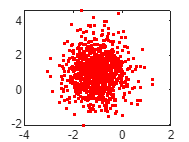

m1 = [-1,1];
s1 = [0.4 0; 0 1];
X1 = mvnrnd(m1,s1,1000);
figure;
plot(X1(:,1),X1(:,2),'.',Color="red");

- Cada una de las dimensiones de cada observación. Tenemos 1000 observa.ciones con dos características.

- El operador X1(:,1) selecciona la primera característica y el otro pues la segunda.

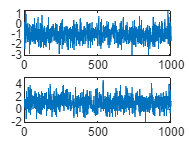

figure
hold on
subplot(2,1,1)
plot(X1(:,1));
subplot(2,1,2)
plot(X1(:,2))

- Si es coherente porque la primera característica tiene una menor variabilidad haciendo caso a la distribución que se ha definido la matriz de covarianzas.

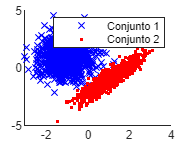

ax = 1:1000;
m2 = [1,-1];
s2 = [0.5 0.6; 0.6 0.9];
X2 = mvnrnd(m2,s2,1000);
figure
hold on
plot(X1(:,1),X1(:,2),'x',Color="blue");
plot(X2(:,1),X2(:,2),'.',Color="red");
legend('Conjunto 1', 'Conjunto 2');

- El parámetro de la matriz más grande del segundo conjunto hace que se estire.

X = [X1;X2];
G = [ones([1 1000]) 2*ones([1 1000])];

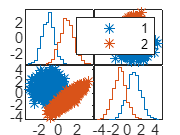


gplotmatrix(X,[],G,[],'*');

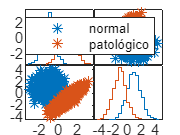

etiquetas = {};
for i = 1:length(G)
    switch G(i)
        case 1
            etiquetas{i} = 'normal';
        case 2
            etiquetas{i} = 'patológico';
    end
end
gplotmatrix(X,[],etiquetas',[],'*');

m = mean(X);

m =    -0.0056    0.0000


- No tiene sentido hacerla para todas a la vez pues la muestra está formada por dos señales con distribución de probabilidad diferente

ans =     0.4921    0.8749
